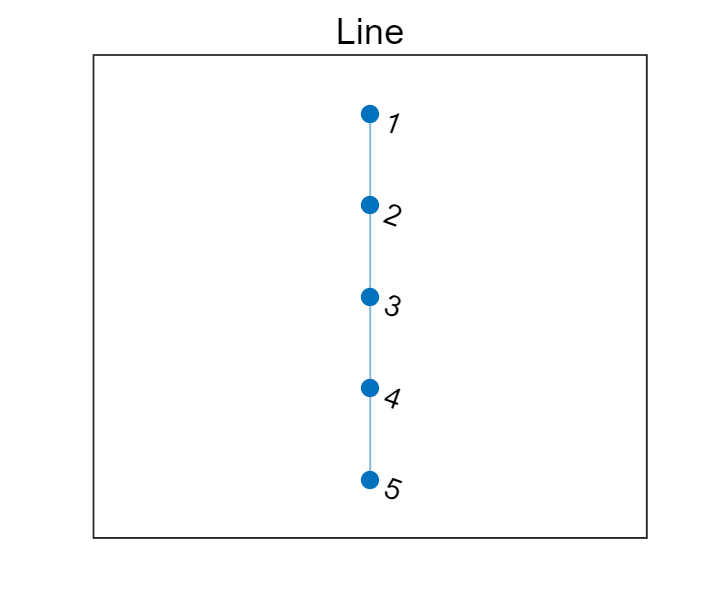

% Line, Ring, Star, Fully Connected Graph
% All graphs have 5 vertices and are represented as adjacency matrixes
line = [0, 1, 0, 0, 0;
        1, 0, 1, 0, 0;
        0, 1, 0, 1, 0;
        0, 0, 1, 0, 1;
        0, 0, 0, 1, 0];

ring = [0, 1, 0, 0, 1
        1, 0, 1, 0, 0;
        0, 1, 0, 1, 0;
        0, 0, 1, 0, 1;
        1, 0, 0, 1, 0;];

star = [0, 0, 1, 0, 0;
        0, 0, 1, 0, 0;
        1, 1, 0, 1, 1;
        0, 0, 1, 0, 0;
        0, 0, 1, 0, 0];

fulConGraph = [0, 1, 1, 1, 1;
               1, 0, 1, 1, 1;
               1, 1, 0, 1, 1;
               1, 1, 1, 0, 1;
               1, 1, 1, 1, 0];

adjGraphs = {line, ring, star, fulConGraph};

set(gcf,'Position',[100 100 260 220]);
plot(graph(line));
title("Line")

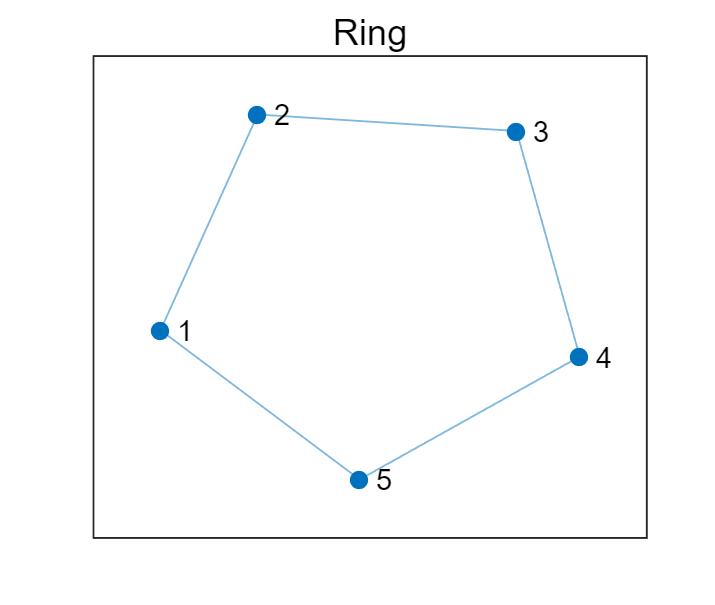

plot(graph(ring));
title("Ring")

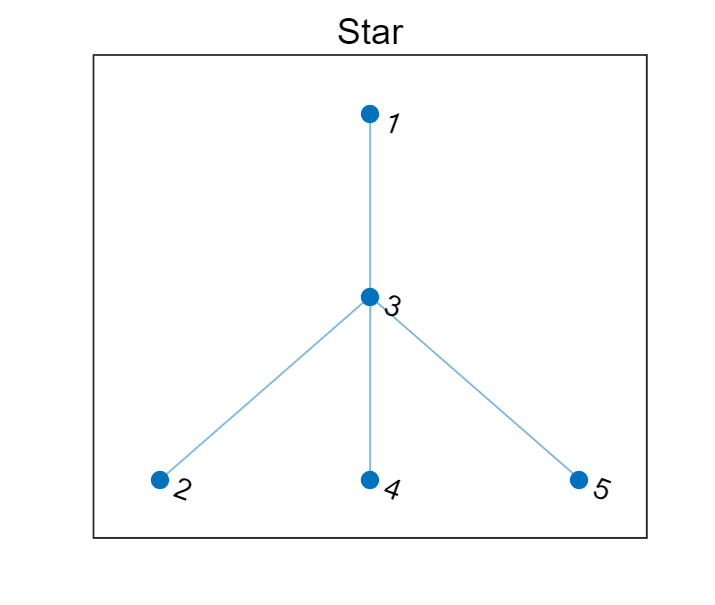

plot(graph(star));
title("Star")

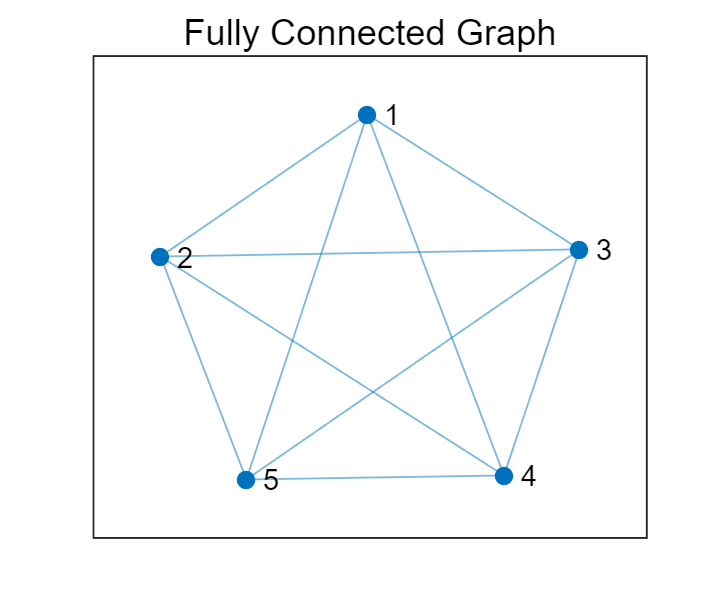

plot(graph(fulConGraph));
title("Fully Connected Graph")

% Calculate the average path length
results = zeros(1, 5);
results(1) = cal_avg_path_len(line);
results(2) = cal_avg_path_len(ring);
results(3) = cal_avg_path_len(star);
results(4) = cal_avg_path_len(fulConGraph);
fprintf("Average Path Length\n" ...
    + "Line: " + results(1) + "\n" ...
    + "Ring: " + results(2) + "\n" ...
    + "Star: " + results(3) + "\n" ...
    + "Fully Connected Graph: " + results(4) + "\n");

Average Path Length
Line: 2
Ring: 1.5
Star: 1.6
Fully Connected Graph: 1


% Calculate the diameter (maximal path length)
results = zeros(1, 5);
results(1) = cal_diameter(line);
results(2) = cal_diameter(ring);
results(3) = cal_diameter(star);
results(4) = cal_diameter(fulConGraph);
fprintf("Diameter (Maximal Path Length)\n" ...
    + "Line: " + results(1) + "\n" ...
    + "Ring: " + results(2) + "\n" ...
    + "Star: " + results(3) + "\n" ...
    + "Fully Connected Graph: " + results(4) + "\n");

Diameter (Maximal Path Length)
Line: 4
Ring: 2
Star: 2
Fully Connected Graph: 1


% Calculate the total number of links
results = zeros(1, 5);
results(1) = cal_link_num(line);
results(2) = cal_link_num(ring);
results(3) = cal_link_num(star);
results(4) = cal_link_num(fulConGraph);
fprintf("Total Number of Links\n" ...
    + "Line: " + results(1) + "\n" ...
    + "Ring: " + results(2) + "\n" ...
    + "Star: " + results(3) + "\n" ...
    + "Fully Connected Graph: " + results(4) + "\n");

Total Number of Links
Line: 4
Ring: 5
Star: 4
Fully Connected Graph: 10


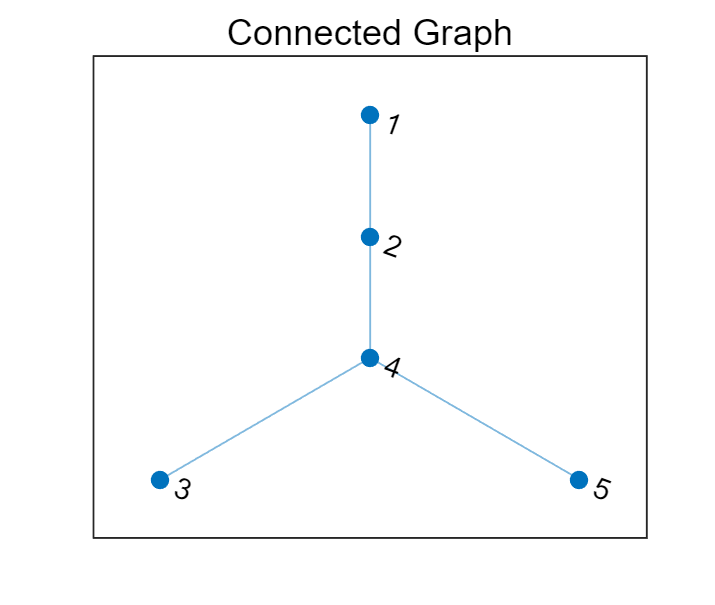

% Create one connected and one not connected graph
conGraph = [0, 1, 0, 0, 0;
            1, 0, 0, 1, 0;
            0, 0, 0, 1, 0;
            0, 1, 1, 0, 1;
            0, 0, 0, 1, 0];

noConGraph = [0, 1, 1, 1, 0;
              1, 0, 1, 1, 0;
              1, 1, 0, 1, 0;
              1, 1, 1, 0, 0;
              0, 0, 0, 0, 1];

plot(graph(conGraph));
title("Connected Graph")

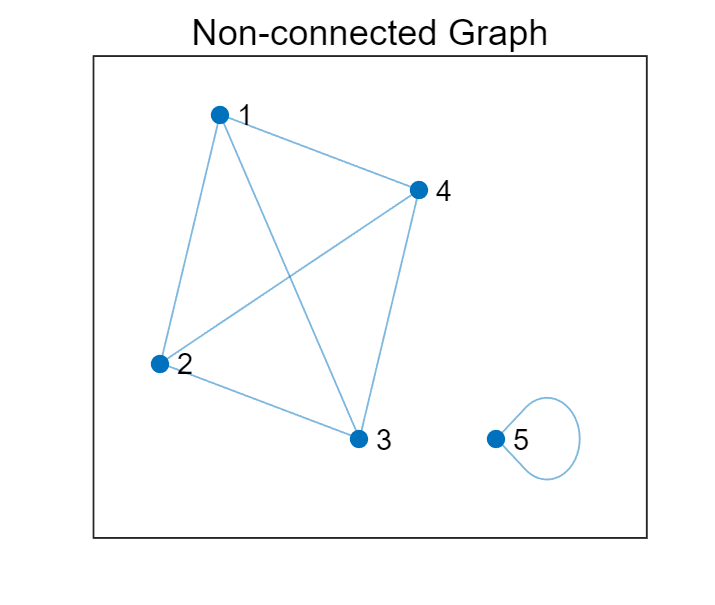

plot(graph(noConGraph));
title("Non-connected Graph")

% Check that G is connected
results = zeros(1, 2);
results(1) = check_connected(conGraph);
results(2) = check_connected(noConGraph);
fprintf("Connected Graph: " + results(1) + "\n" ...
        + "Non-connected Graph: " + results(2) + "\n");

Connected Graph: 1
Non-connected Graph: 0
